#  ENME462 Studio 10 Root Locus Design: PI and Lag Compensators

by Xie Zheng

Section 0101 W 1:00PM - 2:50PM

Github: [https://github.com/XieGT/Control_Studios](https://github.com/XieGT/Control_Studios)

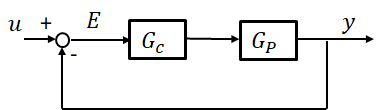

**Close-loop transfer function:**


$$T(s)=\frac{G_c(s)G_p(s)}{1+G_c(s)G_p(s)}$$


**Characteristic equation :**


$$1+G_c(s)G_p(s)=0$$


Magnitude condtion:


$$|G_c(s)G_p(s)|=1$$


Phase condition:


$$\angle G_c(s)G_p(s)=180^o$$


## System Response:

***Steady-state error (unity feedback)***

Position constant: $K_p=\lim_{s\rightarrow0}G(s)$        

Velocity constant: $K_v=\lim_{s\rightarrow0}sG(s)$        

Acceleration constant: $K_a=\lim_{s\rightarrow0}s^2G(s)$

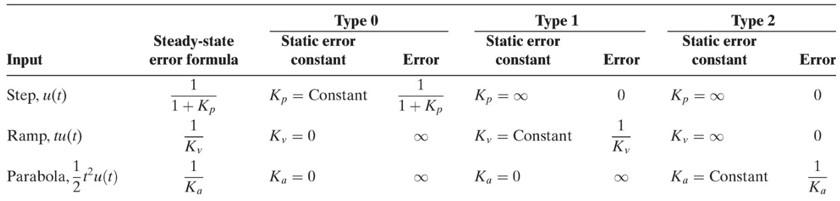

## Compensators: 

**Proportional Compensators **


$$G_c(s)=K$$


**Steady-state error Compensators **

*i) ****PI**** compensators*


$$G_c(s)=K_P+\frac{K_I}{s}=K_P\cdot \frac{(s+K_i/K_P)}{s}$$


PI compensator adds a pole at he origin and a zero close to the origin to prevent the additional pole from significantly distorting the shape of the original system's root locus. 

ii) **Lag** compensators


$$G_c(s)=\frac{s+z_c}{s+p_c}, \qquad |z_c|>|p_c| $$


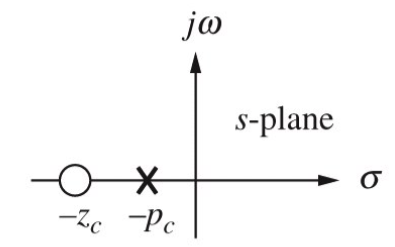

Lag compensator increase the statc error constants, without distorting the shape of the original systems' root locus.

s = 50+50j;
Kp = 100;
Ki = 0.1;
Gc_pi = (s + Ki/Kp)/s

Gc_pi =    1.0000 - 0.0000i



zc = 0.2;
pc = 0.1;
Gc_lag = (s+zc) / (s+pc)

Gc_lag =    1.0010 - 0.0010i


## **Example 1**

The figure below shos a two-tank system. The liquid inflow the upper tank can be controoled using a valve and is represented by $F_0
$. The upper tank's outflow equals the lower tank's inflow and is represented by $F_1$. The outflow of the lower tank is $F_2$. The control design objective is to control the liquid level in the lower tank $y(t)$

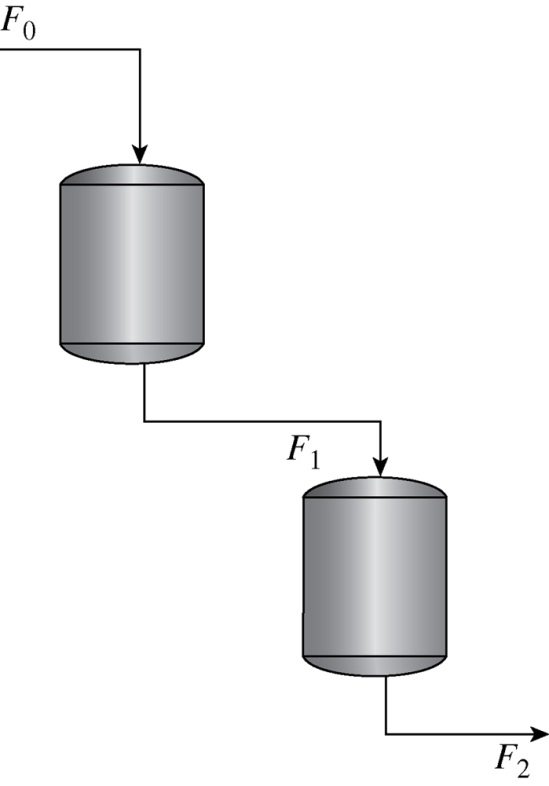

The open-loop transfer function 


$$G_p(s)=\frac{Y(s)}{F_0(s)}=\frac{a_2a_3}{s^2+(a_1+a_4)s+a_1a_4}$$


where $a_1=0.04, \quad a_2=0.0187, \quad a_3=1, \quad a_4= 0.227$

i) Consider the system in a unity feedback configuration. Plot the root locus and determine the steady state error.


$$K_p=\lim_{s \rightarrow0}G_p(s)=\lim_{s \rightarrow0}\frac{a_2a_3}{s^2+(a_1+a_4)s+a_1a_4}=\frac{a_2a_3}{a_1a_4}=2.0595\\
e_{ss}=\frac{1}{1+K_p}=0.3269$$


a = [0.04, 0.0187, 1, 0.227];
s = zpk('s');
Gp = a(2)*a(3)/(s^2 + (a(1)+a(4))*s + a(1)*a(4))


Gp =
 
        0.0187
  ------------------
  (s+0.04) (s+0.227)
 
Continuous-time zero/pole/gain model.



Kp = a(2)*a(3)/(a(1)*a(4))

Kp = 2.0595

ess = 1/(1+Kp)

ess = 0.3269

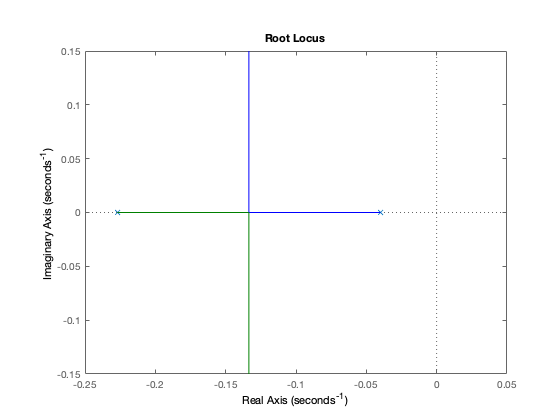

rlocus(Gp)

T_origin = feedback(Gp,1)


T_origin =
 
           0.0187
  ------------------------
  (s^2 + 0.267s + 0.02778)
 
Continuous-time zero/pole/gain model.



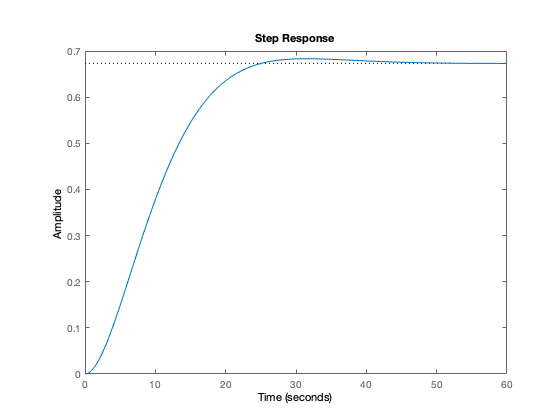

step(T_origin)

ii) Design a lag compensator to yield a 10% steady-state error to step inputs.

Goal:              $\hat{e}_{ss}=\frac{1}{1+\hat{K}_p}=0.1 \rightarrow \hat{K}_p=9$

Lag compensator $G_c(s)=\frac{s+z_c}{s+p_c}$


$$\hat{K}_p=\lim_{s\rightarrow0}G(s)G_c(s)=\frac{a_2a_3}{a_1a_4}\cdot\frac{z_c}{p_c}=K\cdot\frac{z_c}{p_c}\\
\frac{z_c}{p_c}=\hat{K}_p/K=4.3701$$


Assume $p_c=0.01$ then $z_c=0.0437$

hat_Kp = 9;
zc_d_pc = hat_Kp / Kp

zc_d_pc = 4.3701

pc = 0.01;
zc = pc * zc_d_pc;
Gc = (s+zc) / (s+pc)


Gc =
 
  (s+0.0437)
  ----------
   (s+0.01)
 
Continuous-time zero/pole/gain model.



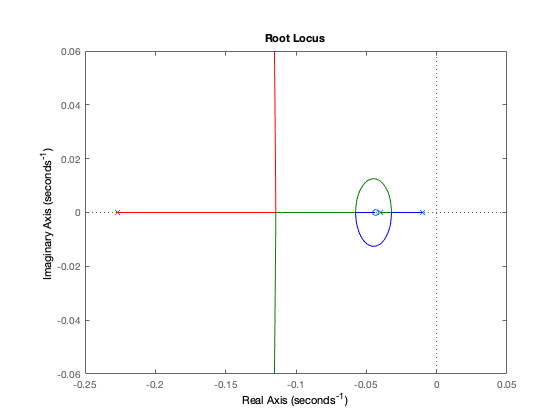

rlocus(Gc*Gp)

iii) Plot the step response for i) and ii) on the same plot.

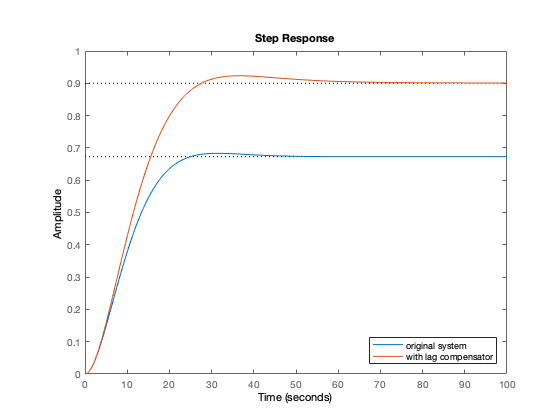

T_lag = feedback(Gp*Gc,1);
step(T_origin,T_lag)
legend('original system','with lag compensator','Location','southeast')